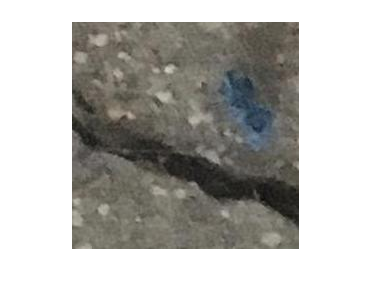

I0 = imread("../../data/data/Concrete Crack Images/00146.jpg");
imshow(I0);

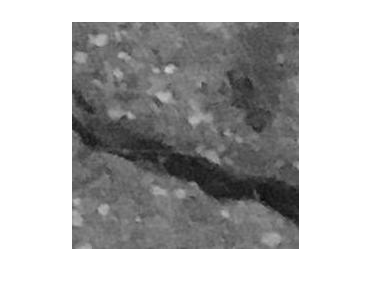

I = im2gray(I0);
imshow(I)


nThresh = 2;
threshValues = multithresh(I, nThresh)

threshValues = 1×2 の uint8 行ベクトル
    73   110


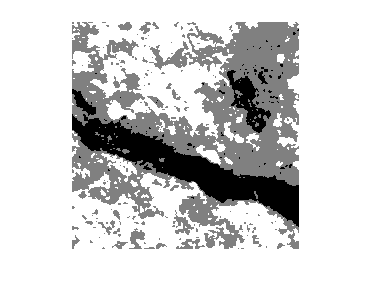


L = imquantize(I,threshValues);
imshow(L,[])

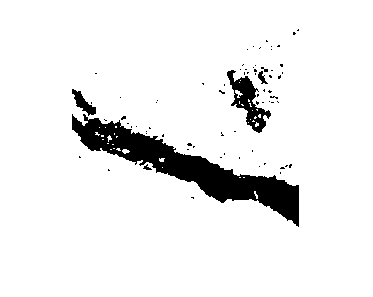


BW = L > 1;
imshow(BW)

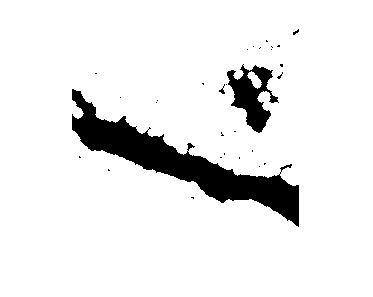


se = strel("disk",4,0);

BW = imopen(BW,se);
imshow(BW)

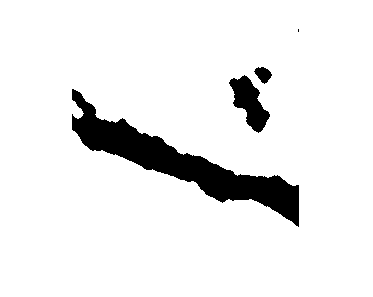

BW = imclose(BW,se);
imshow(BW)

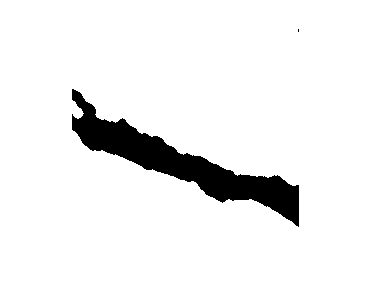

BW = imfill(BW, "holes");
imshow(BW)

BW = imcomplement(BW);
imshow(BW)

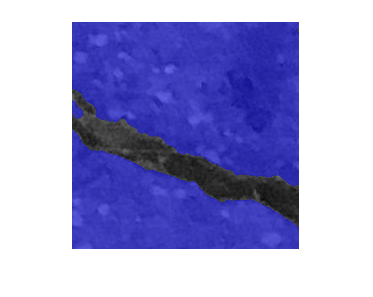

maskOn = labeloverlay(I,BW);
imshow(maskOn)

imshow(L,[])

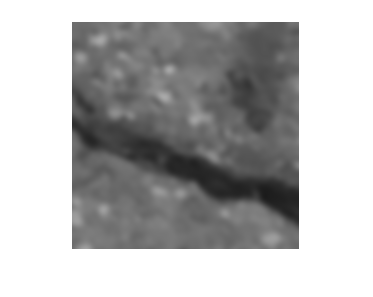


stdev = 3;
If = imgaussfilt(I,stdev);
imshow(If)

threshValues = multithresh(If, nThresh)

threshValues = 1×2 の uint8 行ベクトル
    74   106


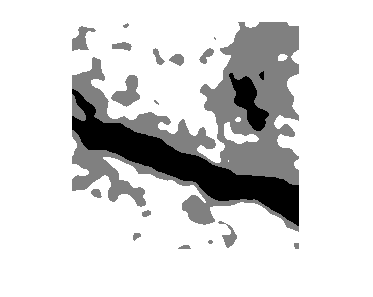

Lf = imquantize(If, threshValues);
imshow(Lf,[])

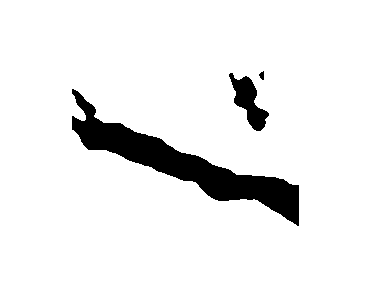

BWf = Lf > 1;
imshow(BWf)

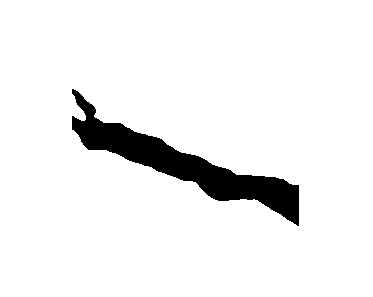

BWf = imfill(BWf,"holes");
imshow(BWf)

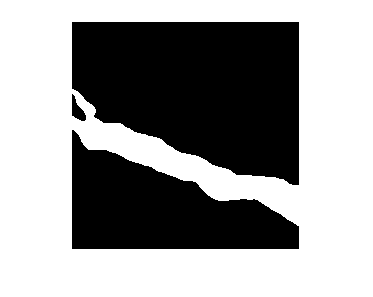

BWf = imcomplement(BWf);
imshow(BWf)

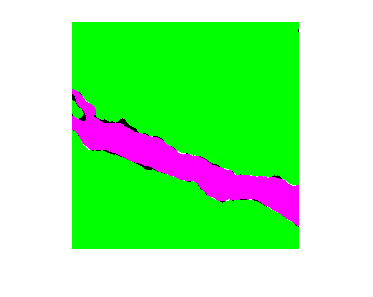

imshowpair(BW, BWf)

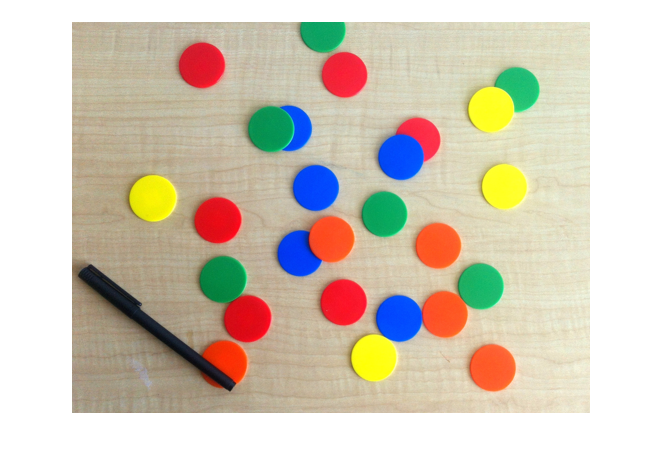

RGB = imread("coloredChips.png");
imshow(RGB)

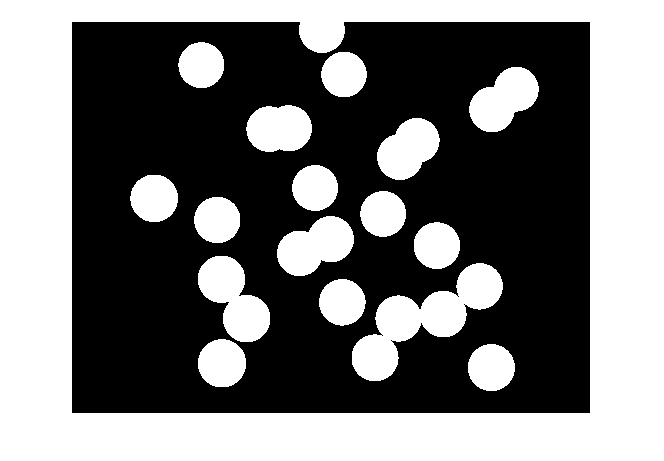

BWdark = segmentChipsDark(RGB);
BWbright = segmentChipsBright(RGB);
BW = BWbright | BWdark;
imshow(BW)

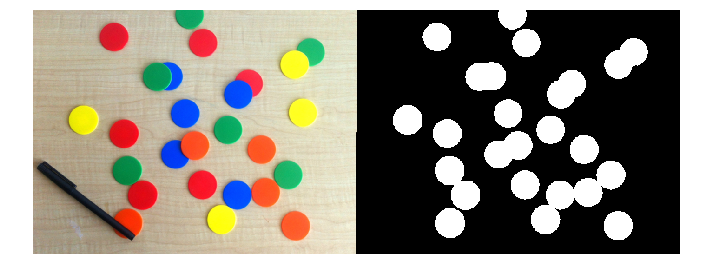

montage({RGB, BW})

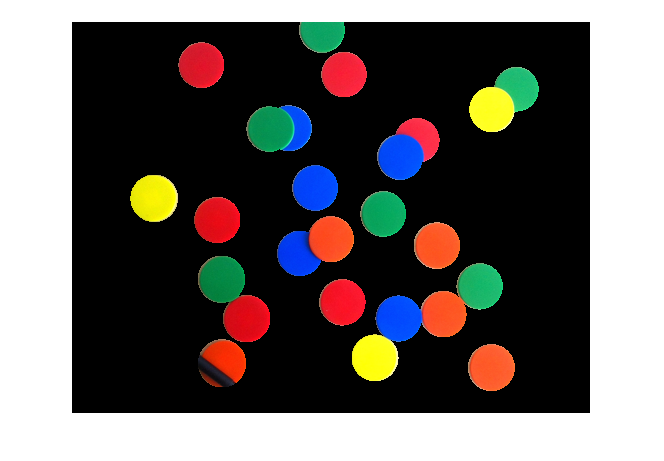

maskedImage = RGB;
maskedImage(repmat(BW,[1,1,3]) == 0) = 0;
imshow(maskedImage)

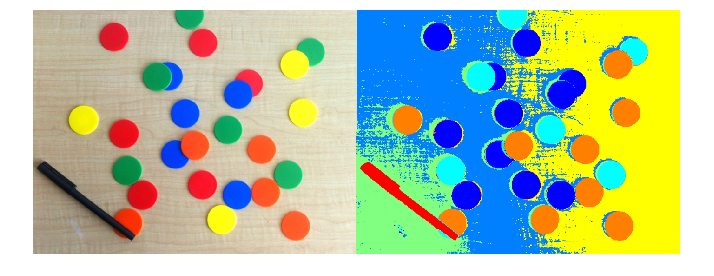

HSV = rgb2hsv(RGB);
K = 7;
labels = imsegkmeans(im2single(HSV), K);
%labels = imsegkmeans(HSV, K);
montage({RGB, label2rgb(labels)})

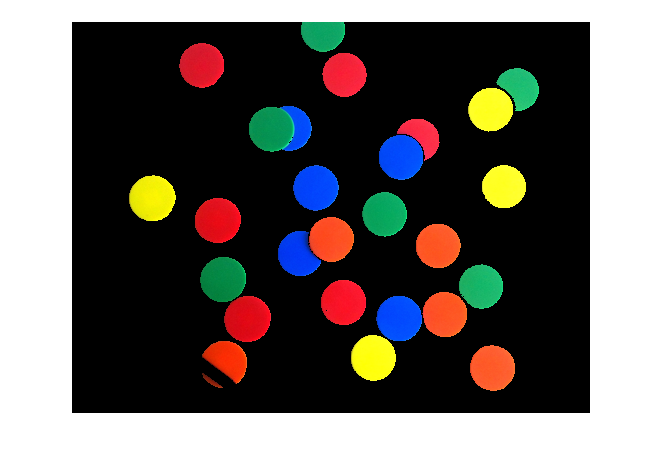

chipmask = HSV(:,:,2) > 0.75;
HSVchip = HSV;
%HSVchip(~repmat(chipmask,[1,1,3])) = 0;
HSVchip(repmat(~chipmask,1,1,3)) = 0;
imshow(hsv2rgb(HSVchip))

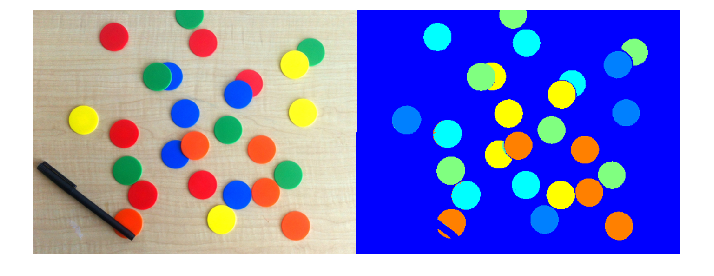

K = 6;
labels = imsegkmeans(im2single(HSVchip),K);
montage({RGB,label2rgb(labels)})

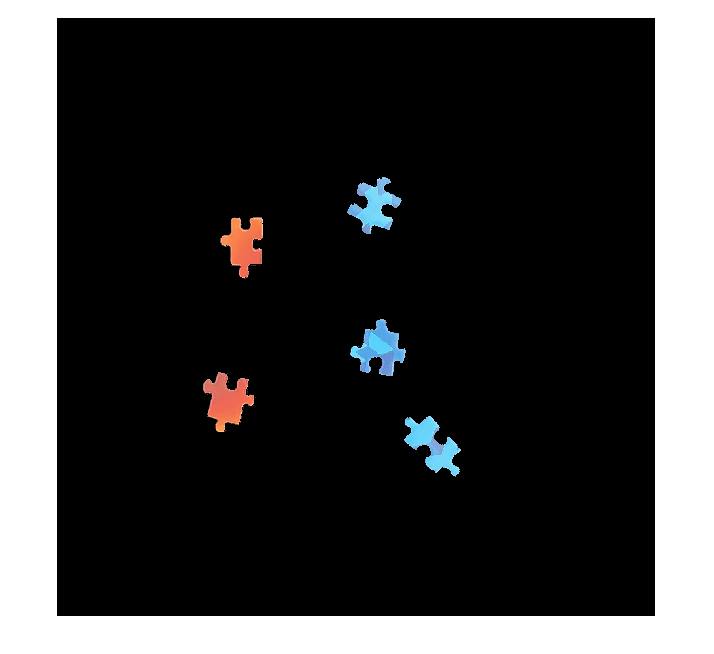

puzzleimg = imread("../../data/Data/MathWorks Images/MathWorks Puzzle/Puzzle_06.jpg");
HSV = rgb2hsv(puzzleimg);
chipmask = HSV(:,:,2) > 0.3;
HSVchip = HSV;
HSVchip(~repmat(chipmask,[1,1,3])) = 0;
imshow(hsv2rgb(HSVchip))

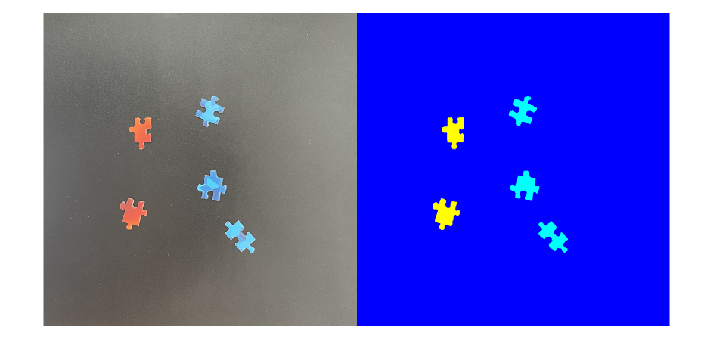

K = 3;
labels = imsegkmeans(im2single(HSVchip),K);
montage({puzzleimg, label2rgb(labels)})

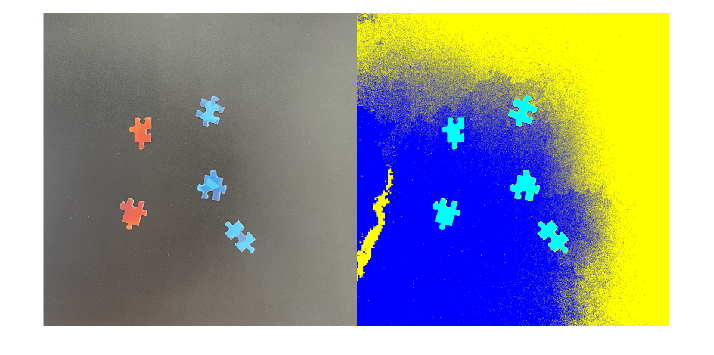

HSV = rgb2hsv(puzzleimg);
K = 3;
labels = imsegkmeans(im2single(HSV),K);
montage({puzzleimg,label2rgb(labels)})

clear
close all
clc

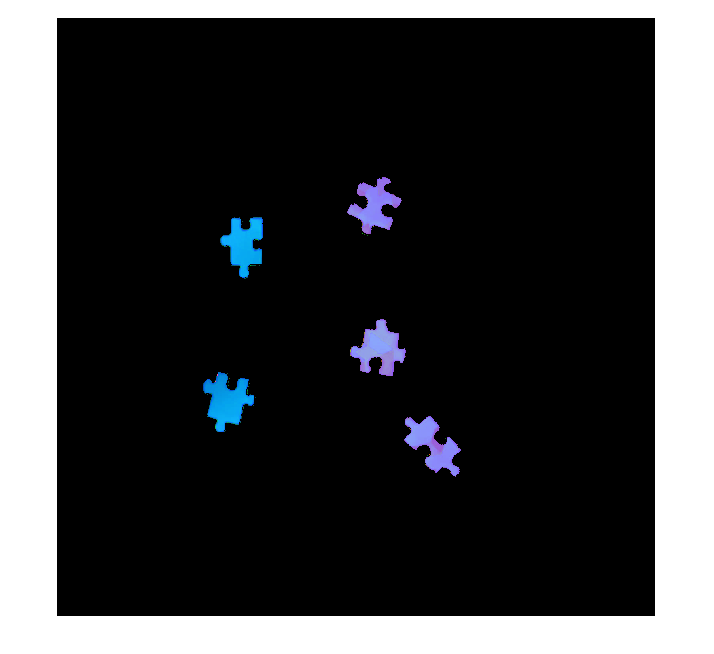

img = imread("../../data/Data/MathWorks Images/MathWorks Puzzle/Puzzle_06.jpg");
imghsv = rgb2hsv(img);
BW = imghsv(:,:,2) > 0.3;
%imshow(BW)
HSVmasked = imghsv;
HSVmasked(~repmat(BW,[1,1,3])) = 0;
imshow(HSVmasked)

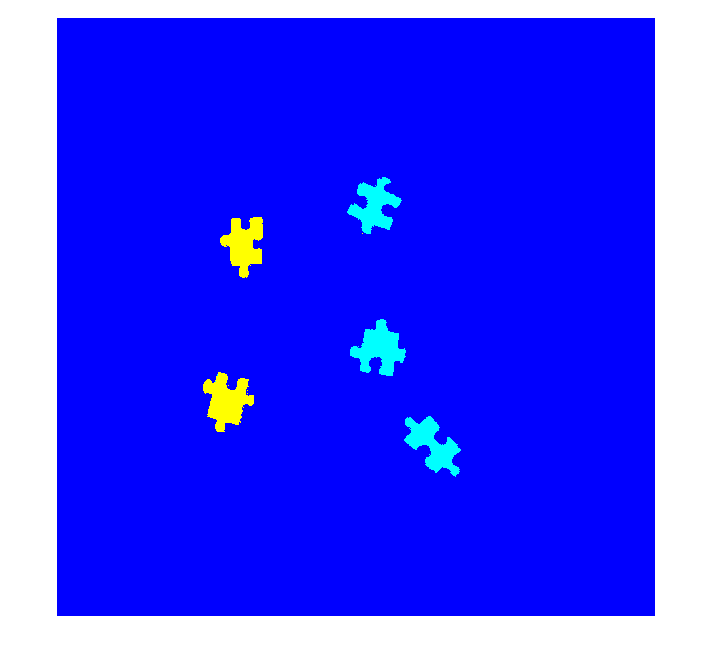

K = 3;
labels = imsegkmeans(im2single(HSVmasked),K);
imshow(label2rgb(labels))

imgGray = im2gray(img);

se = strel("rectangle",[3,6]);

se = strel は、次のプロパティをもつ rectangle の形状の構造化要素です:

      Neighborhood: [3×6 logical]
    Dimensionality: 2
